# Sampling, Aliasing and Interpolation

Dr. Matthew Nokleby, Wayne State University. ECE 4330, Winter 2018.

Let's explore the sampling theorem with practical signals and reconstruction filters. We'll start with a sinusoid. What happens if we increase the frequency of a continuous-time sinusoid but keep the sample rate fixed?

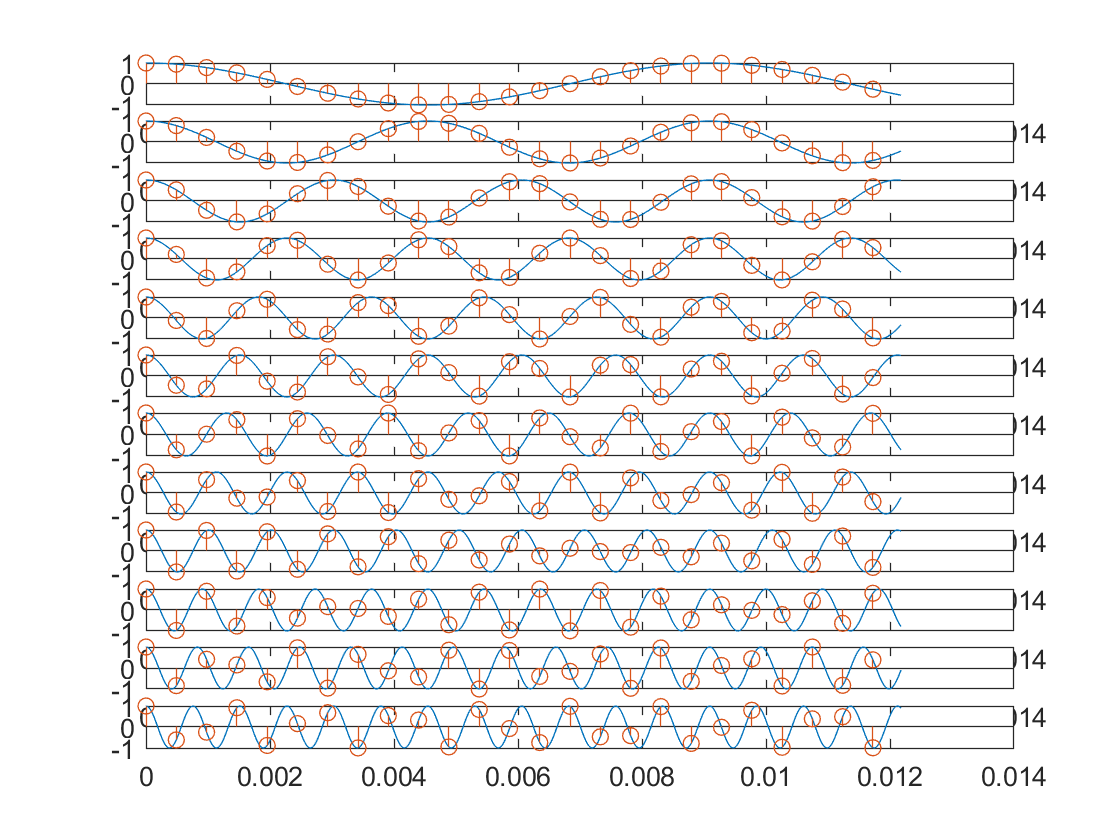

FS = 2048;
tFS = 44100;
DURATION = 1;
NUM_TONES = 12;

NUM_POINTS = 25;
tNUM_POINTS = floor(NUM_POINTS*tFS/FS);

tValues = linspace(0,DURATION,FS*DURATION);
tauValues = linspace(0,DURATION,tFS*DURATION);
for i=1:NUM_TONES
    wc = 2*pi*110*i;
    x_n = cos(wc*tValues);
    x_t = cos(wc*tauValues);
    sound(x_n,FS);
    pause(DURATION + 0.25);
    
    subplot(NUM_TONES,1,i);
    plot(tauValues(1:tNUM_POINTS),x_t(1:tNUM_POINTS));
    hold on;
    stem(tValues(1:NUM_POINTS),x_n(1:NUM_POINTS));
    hold off;
end %for

What's going on? In discrete-time, the highest possible frequency is $\pi$ radians/sample. Once the continuous-time frequency is higher than half the sample rate, x[n] is at a frequency higher than $\pi$, which means that we start *decreasing* the apparent frequency. In other words, if the sample rate is too low, high frequencies get "copied" into low frequency, a phenomenon we call **aliasing**.

Let's try sampling a practical signal. We have to be careful, since MATLAB deals only with discrete-time signals. We'll simulate our continuous-time signal by using a high sample rate.

load train;
DURATION = length(y)/Fs;
tValues = linspace(0,DURATION,length(y));
xOriginal = y;

Our signal is only approximately band-limited. To sample it, we first need to put it through an anti-aliasing filter. We'll use a Butterworth filter for this, and we'll designate the output of the filter $f(t)$. Let's look at the frequency-domain difference in the signals.

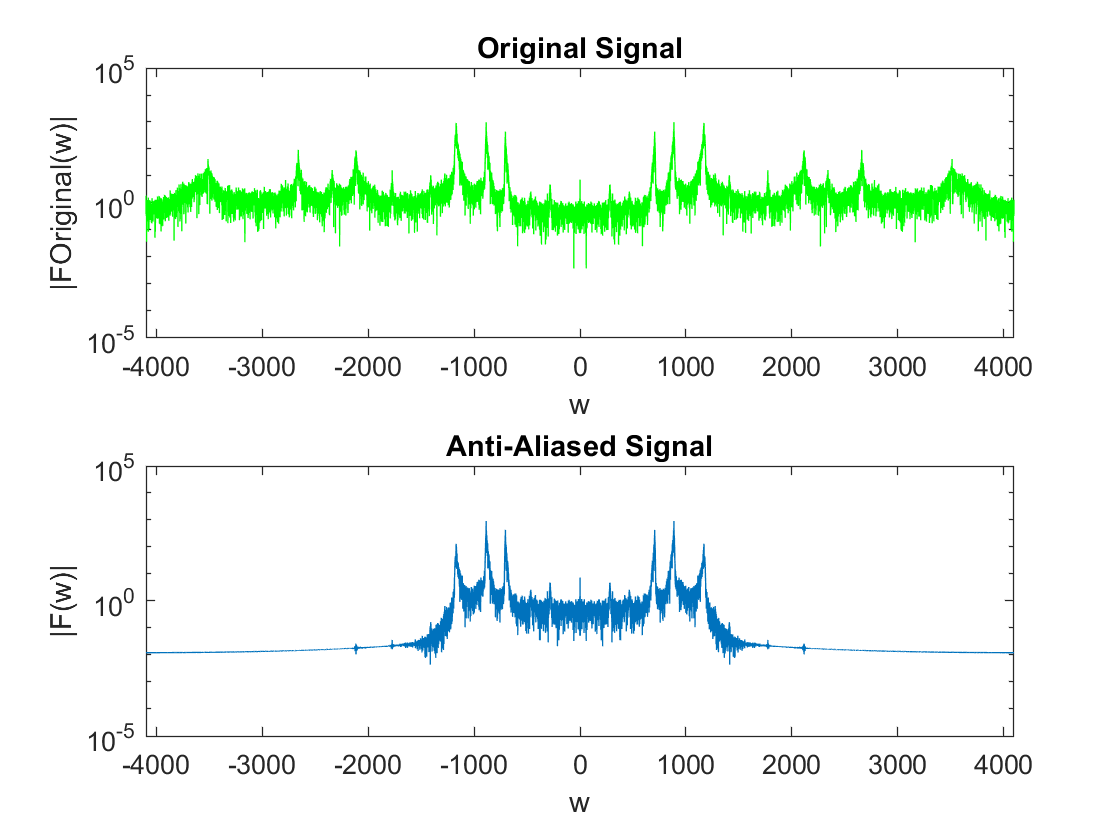

FC = 1000; %cutoff frequency
n = 12; %filter order, I chose this insanely high!

[zb,pb,kb] = butter(n,2*pi*FC,'s');
[b,a] = zp2tf(zb,pb,kb);
%[hb,wb] = freqs(bb,ab,w);

xAA = lsim(b,a,xOriginal,tValues);

XAA = fftshift(fft(xAA));
XOriginal = fftshift(fft(xOriginal));
FfValues = linspace(-Fs/2,Fs/2,Fs*DURATION); %frequency in hz for easier intuition
MAX_FREQ = Fs/2;

close all;
subplot(2,1,1)
semilogy(FfValues,abs(XOriginal),'g');
xlabel('w');
ylabel('|FOriginal(w)|');
title('Original Signal');
xlim([-MAX_FREQ MAX_FREQ]);

subplot(2,1,2);
semilogy(FfValues,abs(XAA));
xlabel('w');
ylabel('|F(w)|');
title('Anti-Aliased Signal');
xlim([-MAX_FREQ MAX_FREQ]);

Let's listen to the difference, too.

sound(xOriginal,Fs);

sound(xAA,Fs);

Let's try sampling at a sampling frequency a bit larger than the Nyquist Rate and see how we go. We'll do this by impulse train sampling.

SAMPLING_FREQUENCY = 3000;

p = zeros(Fs*DURATION,1); %Generate an impulse train
p(1:round(Fs/SAMPLING_FREQUENCY):end) = 1;
xBar = xAA.*p;

Let's see the effect of sampling in the time domain by superimposing the original and sampled signal.

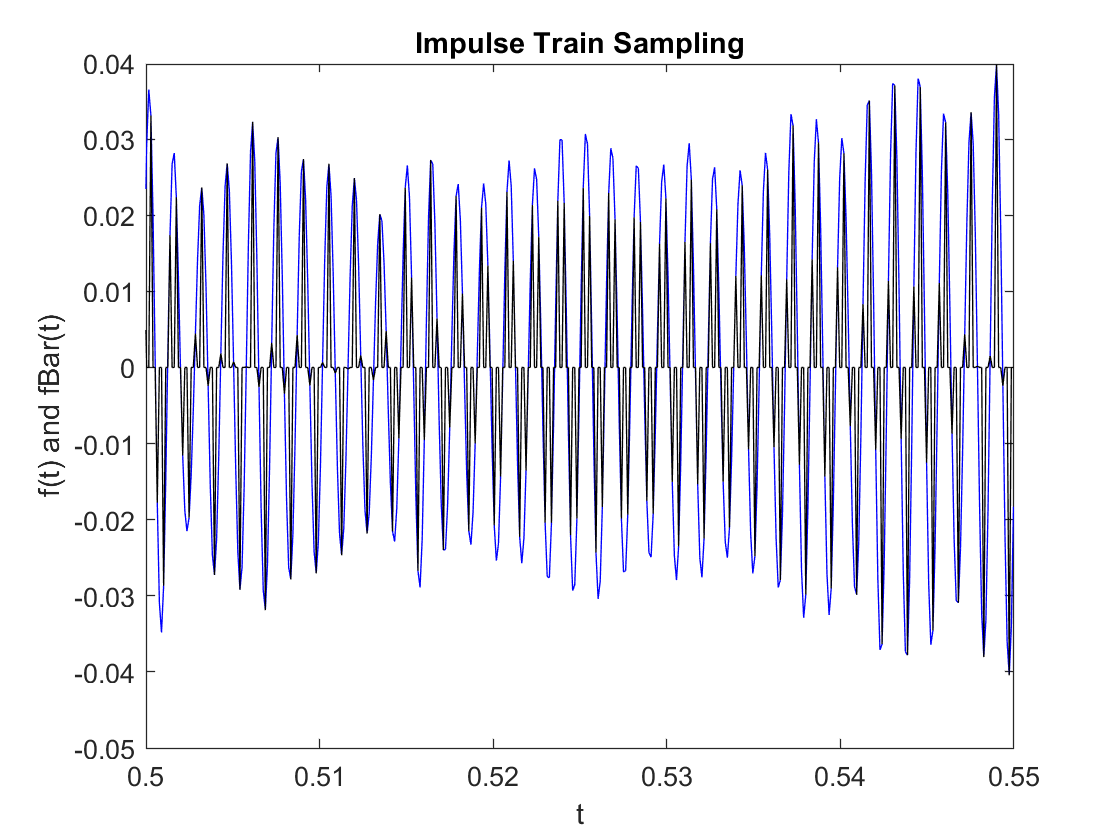

tStart = 0.5;
tFinish = 0.55;
iStart = round(tStart*Fs);
iFinish = round(tFinish*Fs);

close all;
plot(tValues(iStart:iFinish),xAA(iStart:iFinish),'b',tValues(iStart:iFinish),xBar(iStart:iFinish),'k');
xlim([tStart tFinish]);
xlabel('t');
ylabel('f(t) and fBar(t)');
title('Impulse Train Sampling');

Let's look in the frequency domain next.

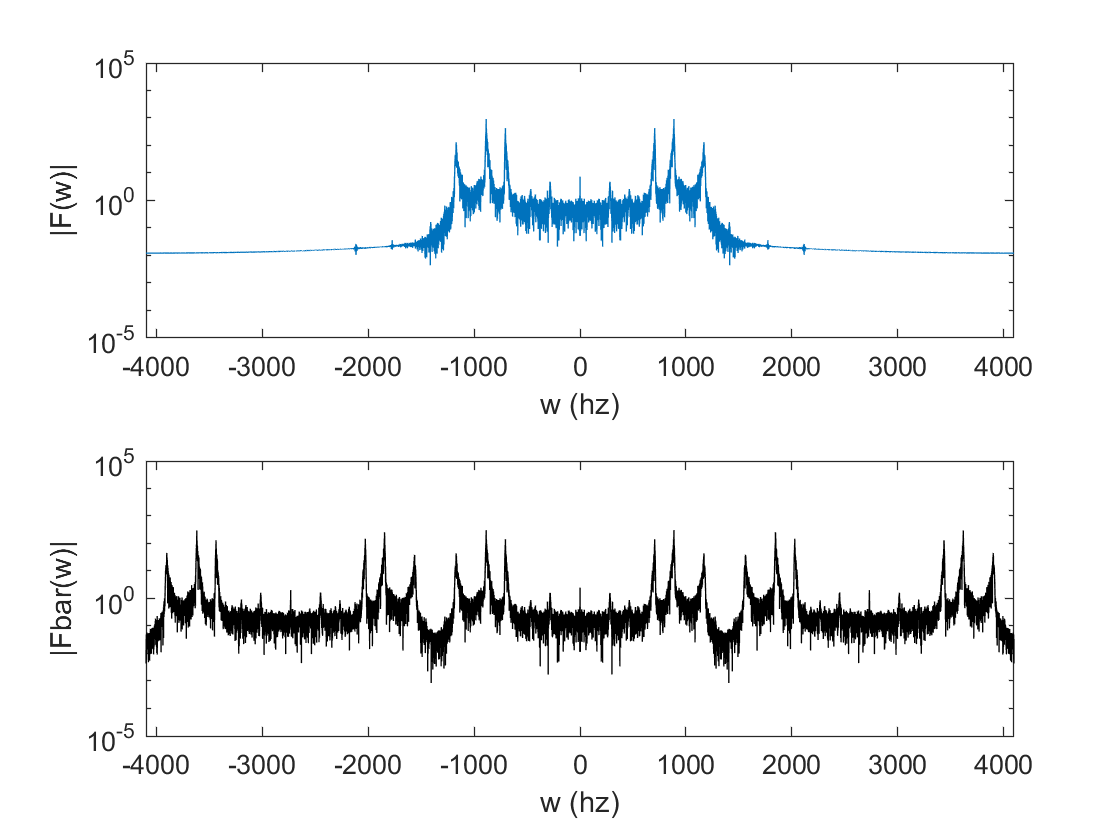

Xbar = fftshift(fft(xBar));
MAX_FREQ = Fs/2;

close all;
subplot(2,1,1);
semilogy(FfValues,abs(XAA));
xlabel('w (hz)');
ylabel('|F(w)|');
xlim([-MAX_FREQ MAX_FREQ]);
subplot(2,1,2);
semilogy(FfValues,abs(Xbar),'k');
xlabel('w (hz)');
ylabel('|Fbar(w)|');
xlim([-MAX_FREQ MAX_FREQ]);

Sure enough, the sampled signal has replicas of the original spectrum. Do they overlap? Did we sample quickly enough? There's only one way to find out for sure, and that's to try to interpolate.

As we've mentioned before, ideal interpolation is impossible because the sinc function is highly non-causal. Again we'll use a Butterworth filter, which is a pretty good approximation of the ideal LPF. Let's design the filter that cuts off at half of the sampling frequency, and look both at its impulse and frequency responses.

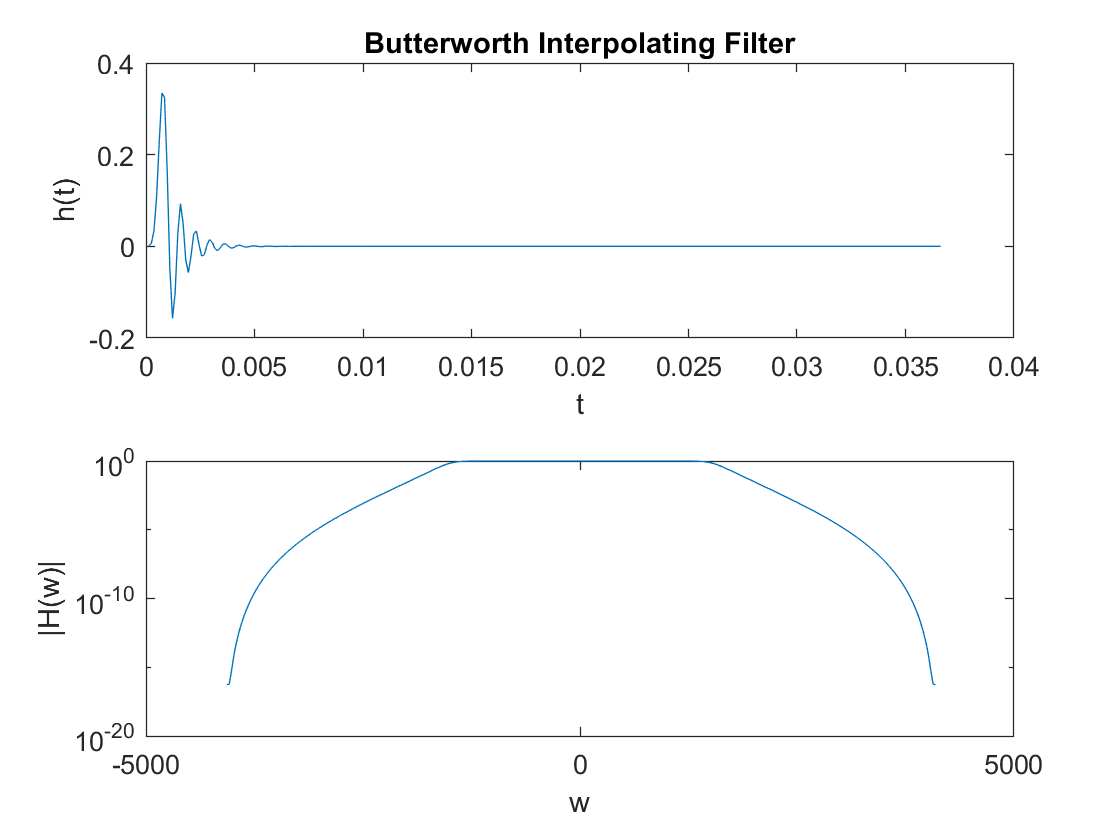

N = 9; %Still a pretty high filter order!
NUM_TAPS = 300;
[B,A] = butter(N,SAMPLING_FREQUENCY/(Fs));
h = filter(B,A, [1 zeros(1,NUM_TAPS-1)]);
H = fftshift(fft(h));
HFValues = linspace(-Fs/2,Fs/2,NUM_TAPS);

close all;
subplot(2,1,1);
plot((1:NUM_TAPS)/Fs,h);
xlabel('t');
ylabel('h(t)');
title('Butterworth Interpolating Filter');
subplot(2,1,2);
semilogy(HFValues,abs(H));
xlabel('w');
ylabel('|H(w)|');

In the frequency domain, it looks like we have a pretty good low-pass filter: the gain is level until the desired frequency, and dives swiftly afterwards. In the time-domain, we see an impulse response that looks sinc-like, but, among other things, has a delay. Let's see how well this does interpolating the sampled signal.

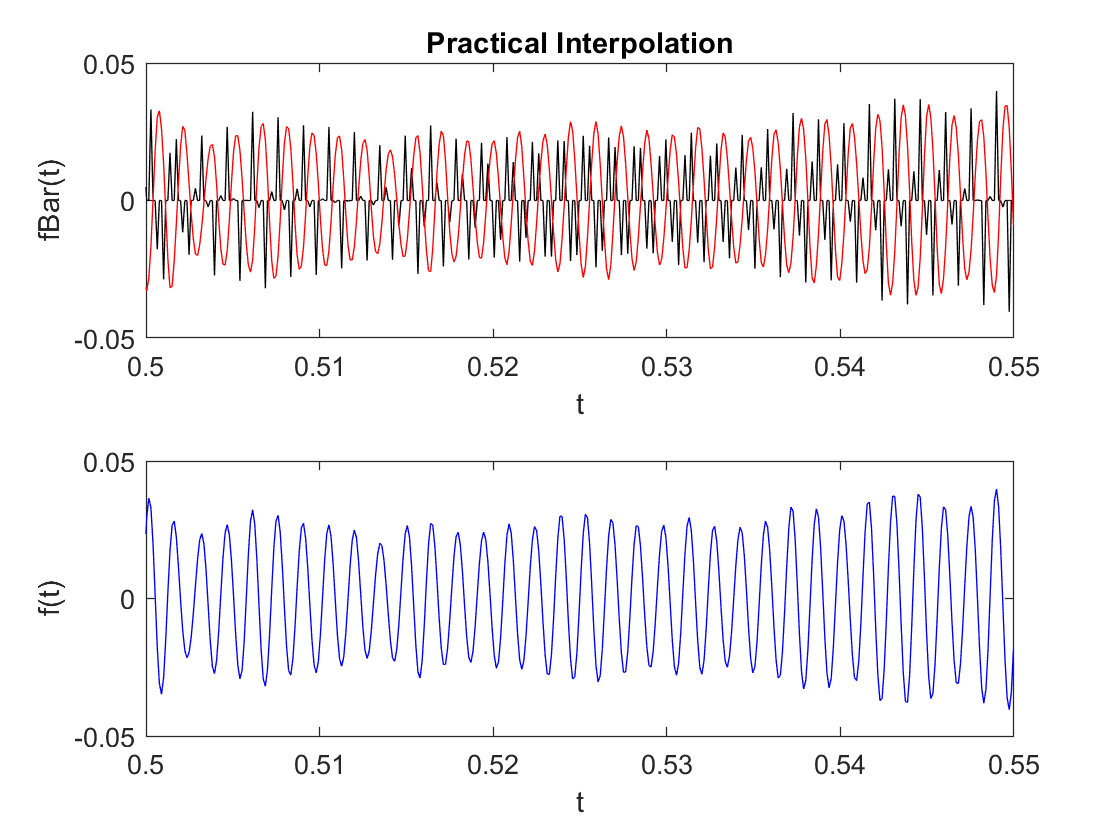

tStart = 0.50;
tFinish = 0.55;
iStart = round(tStart*Fs);
iFinish = round(tFinish*Fs);

xRecovered = Fs/SAMPLING_FREQUENCY*filter(B,A,xBar); %Remember that the interpolation filter multiplies by the sampling period

close all;
subplot(2,1,1);
plot(tValues(iStart:iFinish),xBar(iStart:iFinish),'k',tValues(iStart:iFinish),xRecovered(iStart:iFinish),'r');
xlim([tStart tFinish]);
xlabel('t');
ylabel('fBar(t)');
title('Practical Interpolation');
subplot(2,1,2);
plot(tValues(iStart:iFinish),xAA(iStart:iFinish),'b');
xlim([tStart tFinish]);
xlabel('t');
ylabel('f(t)');

How did we do? It looks a little off, but that's just delay associated with a causal low-pass filter.. We've actually reconstructed the signal with very high accuracy! Let's listen to the result. Original signal first, followed by the reconstructed signal. For fun, let's listen to the sampled signal to appreciate how much sampling disturbs the signal without reconstruction.

sound(xAA,Fs);

sound(xBar,Fs);

sound(xRecovered,Fs);

Now, let's try decreasing the sample rate. At some point the spectral copies will overlap, and we won't be able to recover the original signal. We'll both see and hear the resulting *aliasing* phenomenon.

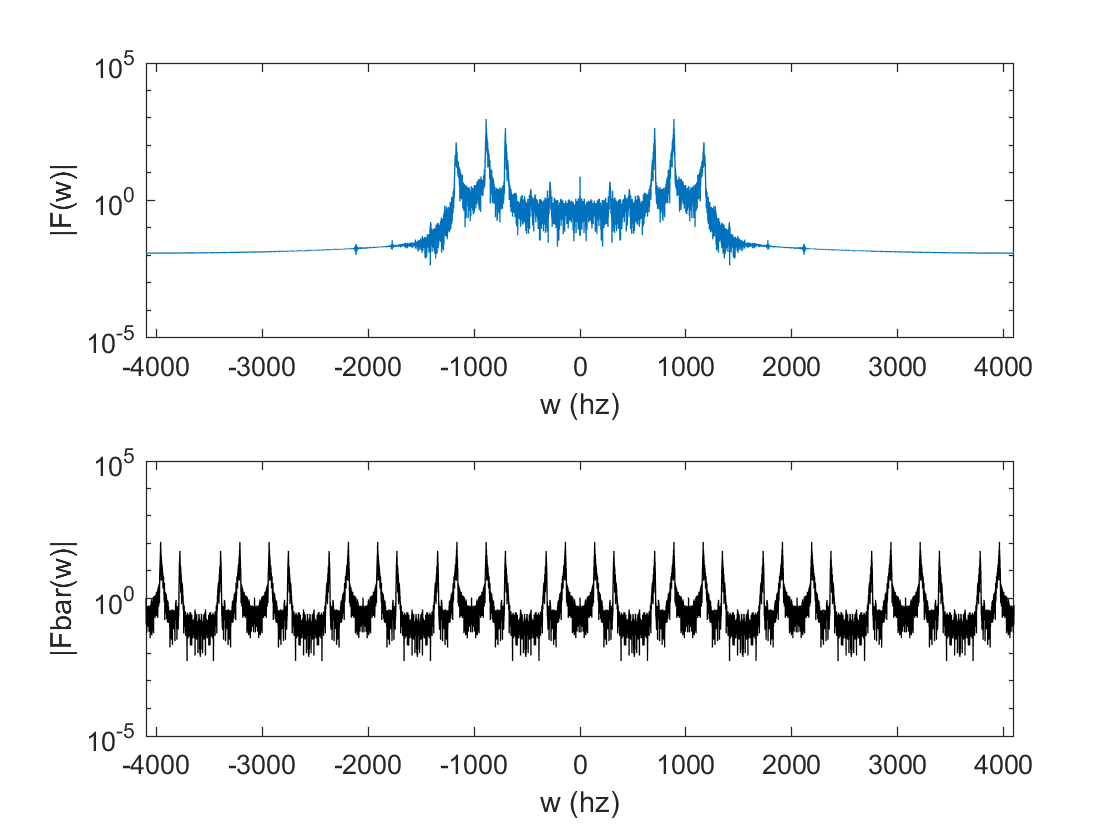

SAMPLING_FREQUENCY = 1000;

p = zeros(Fs*DURATION,1); %Generate an impulse train
p(1:round(Fs/SAMPLING_FREQUENCY):end) = 1;
xBar = xAA.*p;

Xbar = fftshift(fft(xBar));
MAX_FREQ = Fs/2;

close all;
subplot(2,1,1);
semilogy(FfValues,abs(XAA));
xlabel('w (hz)');
ylabel('|F(w)|');
xlim([-MAX_FREQ MAX_FREQ]);
subplot(2,1,2);
semilogy(FfValues,abs(Xbar),'k');
xlabel('w (hz)');
ylabel('|Fbar(w)|');
xlim([-MAX_FREQ MAX_FREQ]);

You can see the overlap increase as we decrease the sampling frequency. We can hear it, too, when we try to interpolate. We'll use a LPF that keeps only one peak of the sampled signal. But the result won't be pretty.

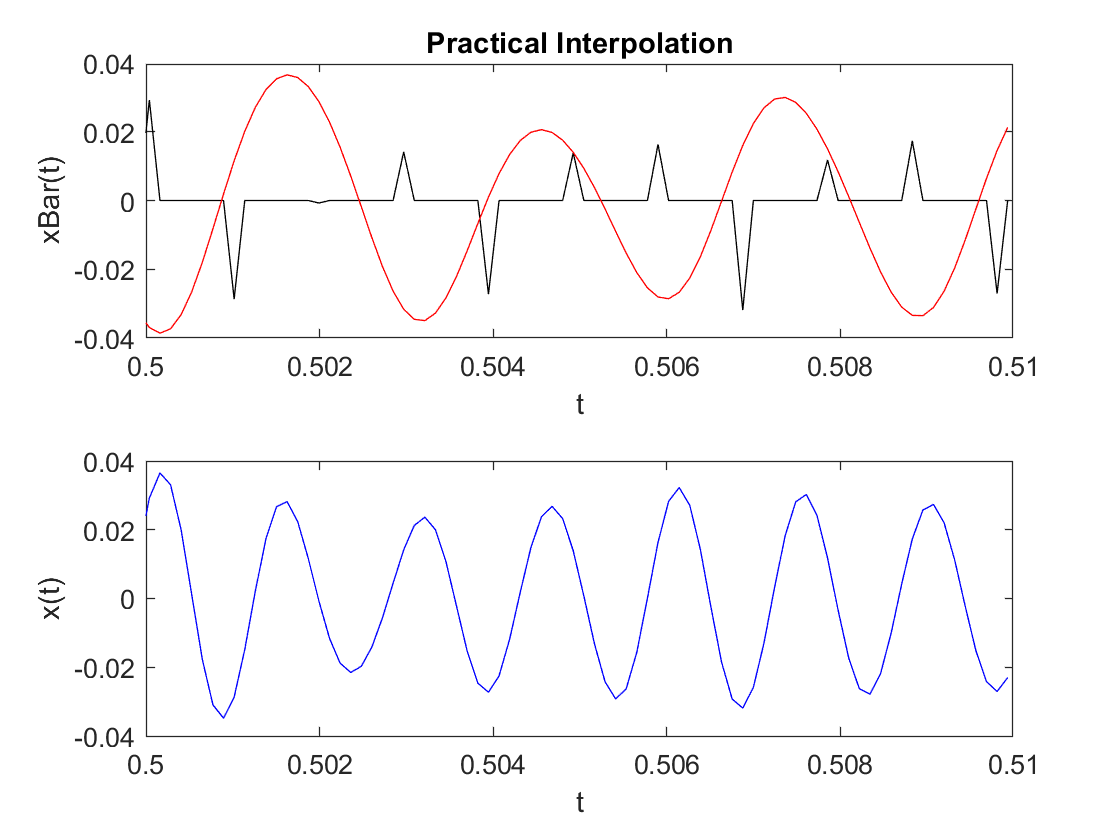

[B,A] = butter(N,SAMPLING_FREQUENCY/(Fs));
xRecovered = Fs/SAMPLING_FREQUENCY*filter(B,A,xBar); %Remember that the interpolation filter multiplies by the sampling period

tStart = 0.50;
tFinish = 0.51;
iStart = round(tStart*Fs);
iFinish = round(tFinish*Fs);

close all;
subplot(2,1,1);
plot(tValues(iStart:iFinish),xBar(iStart:iFinish),'k',tValues(iStart:iFinish),xRecovered(iStart:iFinish),'r');
xlim([tStart tFinish]);
xlabel('t');
ylabel('xBar(t)');
title('Practical Interpolation');
subplot(2,1,2);
plot(tValues(iStart:iFinish),xAA(iStart:iFinish),'b');
xlim([tStart tFinish]);
xlabel('t');
ylabel('x(t)');

sound(xRecovered,Fs);

As we lower the sampling frequency, we get a worse reconstruction. In particular, you hear a strange sort of frequency distortion, where there are signal components at pitches that weren't in the original signal. This is aliasing: The spectral copies overlap, and suddenly a frequency component is pushed to somewhere else in the spectrum. The result is pretty distinctive -- and sounds pretty bad. If a system designer is stuck with a slow sampling frequency, the solution is always to use an anti-aliasing filter prior to sampling. You throw out high-frequency information, but your information-reduced signal makes it through the sampling process uncorrupted.